DATA_PATH = 'D:\PhD\Data\T386_MatlabTest\'; %folder in which the data is located; should end with \
ND2_FNAME = 'T386_20211202_green.nd2';

nd2_file_path = [DATA_PATH ND2_FNAME];
options_other.filename = nd2_file_path;
bright_spikes = [];

[nd2_data, options_other] = nd2ReadWithOptions(options_other);

nd2ReadWithOptions: no num2read parameter in options detected. Using default parameter num2read: []
1 channel found. Started reading out nd2 file.
reading complete image data used 2.84 seconds


nd2_rippleremoved = rippleRemovalWithOptions(nd2_data, bright_spikes, options_other);

Supplying default parameter rnr_ampl_thr: 10.8
Supplying default parameter rnr_win: 40


Supplying default parameter rnr_ampl_thr: 10.8
Supplying default parameter rnr_win: 40


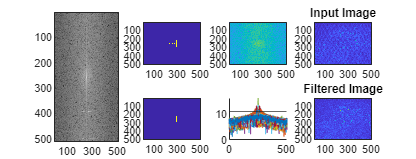

options_other.rnr_plt = true;
rippleRemovalWithOptions(nd2_data, bright_spikes, options_other);

options_other.rnr_plt = false;